# Plot pressure values against volume values as an oriented line plot.

`ax = pVPlot(vValues,vUnits,pValues,pUnits,opts) `plots `pValues` against `vValues` as a single oriented line plot. The x-axis label will be marked in `vUnits` while the y-axis label will be marked in `pUnits`. The optional argument `Title` will be used as the title. The optional argument `LabelEndpoint` is a logical that tracks whether the values at both ends of the path are specified or whether only the starting point is known. The optional argument `showArea` is a logical that tracks whether the signed area under the curve is shown as well. The sign of the area is indicated by the color of the shading with SeriesIndex color 1 representing the positive and SeriesIndex color 2 representing the negative.

## Examples

### Creating Basic P-V Plots

To create a P-V plot at constant 1.3 MPa pressure and volume that increases from 0.8 cm$^3$ to 1.4 cm$^3$:

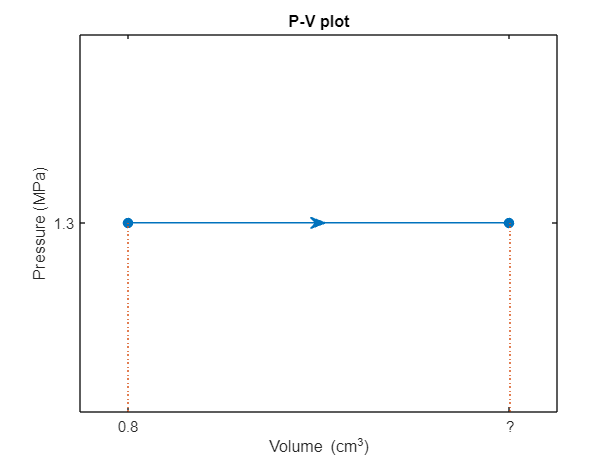

To generate a plot with a specific title in a situation where the pressure values are a function of the volume values. 

Note that on this plot the terminal point is labeled as unknown values. This is to facilitate problem solving in situations where the qualitative behavior matters but the quantitative data may not be known.

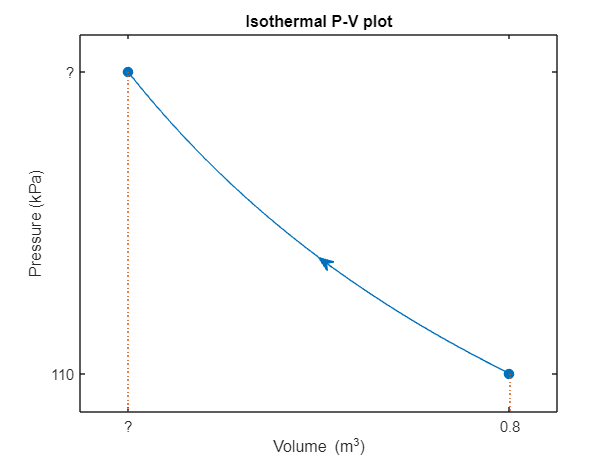

If you do know the data at both endpoints, you can use the shorter command:

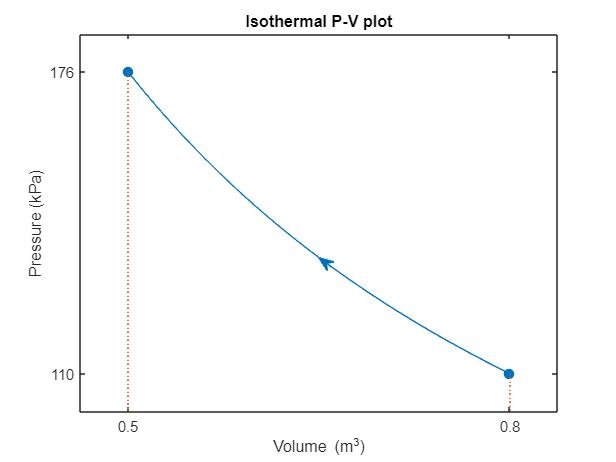

This results in a fully specified plot.

### Showing Work on a P-V Plot

When visualizing work on a P-V plot, by using the optional flag `showArea=true` you can visually estimate the signed area. The following represents work done by the surroundings on the system.

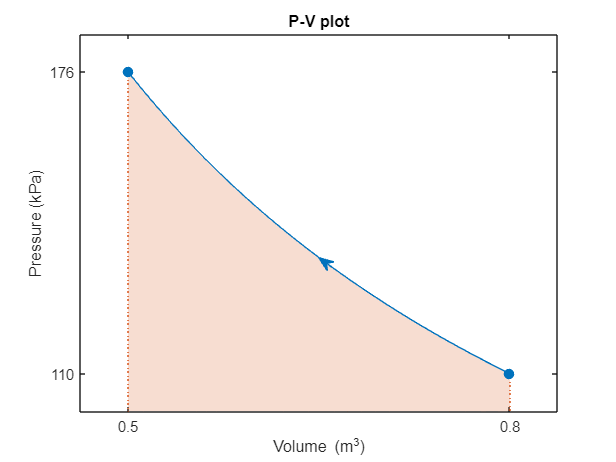

A P-V plot showing the work can also be modified with a specific title. In this example, the total amount of work done by the system is printed in the title.

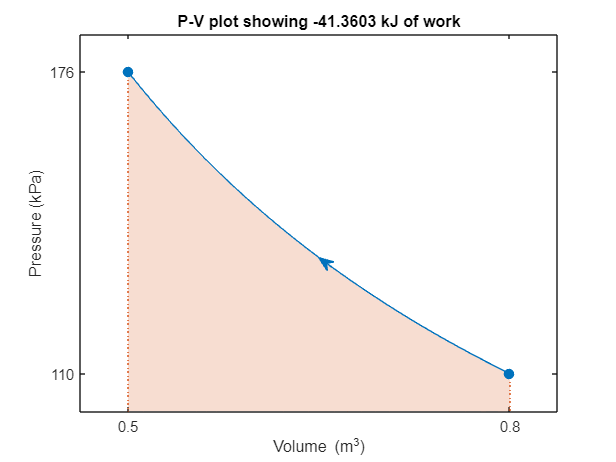

By changing the direction of the path in P-V space, we can create an example with positive work:

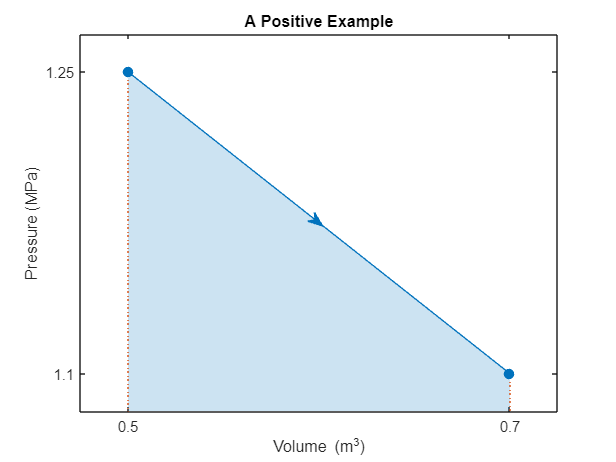

function ax = pvPlot(vValues,vUnits,pValues,pUnits,opts)
arguments
    vValues (1,:) {mustBeReal,mustBeNumeric}
    vUnits (1,1) string
    pValues (1,:) {mustBeReal,mustBeNumeric}
    pUnits (1,1) string
    opts.Title string = "P-V plot"
    opts.flag logical = false
    opts.ShowArea logical = false
    opts.AddArea logical = false
    opts.LabelEndpoint logical = true
end

if opts.AddArea
    ax = gca;
else
    clf
    ax = axes;
    p = plot(ax,vValues,pValues,"SeriesIndex",1);
    xlabel("Volume (" + vUnits + ")")
    ylabel("Pressure (" + pUnits + ")")
    xlim(getBounds(vValues))
    ylim(getBounds(pValues))
    setLabels(vValues,"x",opts.LabelEndpoint)
    setLabels(pValues,"y",opts.LabelEndpoint)
    title(opts.Title)
    ax.NextPlot = "add";
    scatter(ax,[vValues(1) vValues(end)],[pValues(1) pValues(end)],50,"Filled","SeriesIndex",1)

    if vValues(end) ~= vValues(1)
        ax.NextPlot = "add";
        plot(ax,[vValues(1) vValues(1)],[pValues(1) ax.YLim(1)],":","SeriesIndex",2)
        ax.NextPlot = "add";
        plot(ax,[vValues(end) vValues(end)],[pValues(end) ax.YLim(1)],":","SeriesIndex",2)
    else
        ax.NextPlot = "add";
        plot([vValues(1) ax.XLim(1)],[pValues(1) pValues(1)],":","SeriesIndex",2)
        ax.NextPlot = "add";
        plot([vValues(end) ax.XLim(1)],[pValues(end) pValues(end)],":","SeriesIndex",2)
    end
    [axVals,ayVals] = locateArrow(vValues,pValues,ax);
    myArrow = annotation("arrow",axVals,ayVals);
    myArrow.Color = p.Color;
end

if opts.ShowArea || opts.AddArea
    if numel(ax.XTick) > 1
        ax.XTickLabel = string(ax.XTick);
    end

    if numel(ax.YTick) > 1
        ax.YTickLabel = string(ax.YTick);
    end

    hold on
    [~,~,posRegGroup,negRegGroup,~] = plotRegions(pValues,vValues,{ax.Children(1).Color,ax.Children(end).Color});
    hold off

    % Reorder stacking of the plots
    chi = get(gca,"Children");
    set(gca,"Children",flipud(chi))

    posRegGroup.Visible = "on";
    negRegGroup.Visible = "on";
end
end
